# **Capstone: Modern Control Theory**

#### System Design and Analysis: a hands-on approach

Please provide a report on the analysis of the given transformation function based on the following questions, accompanied by thorough analysis and simulation using MATLAB:

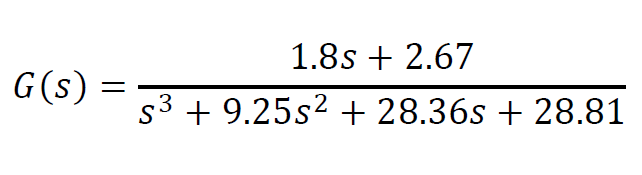

% System Transfer Function
num = [1.8, 2.67];
den = [1, 9.25, 28.36, 28.81];
sys = tf(num, den);

**1.**    Calculate the zeros and poles of the system. Determine whether the open-loop system is stable and minimum phase. Provide a detailed analysis of the system's characteristics.

% Zeros and Poles of the System
sys_zeros = zero(tf(num, den))

sys_zeros = -1.4833

sys_poles = pole(tf(num, den))

sys_poles =    -3.4599
   -3.1285
   -2.6616


nStates = max(size(sys_poles))

nStates = 3

To determine whether the open-loop system is stable, we can look at the locations of the poles. Since all of the poles have negative real parts, the system is *stable*.

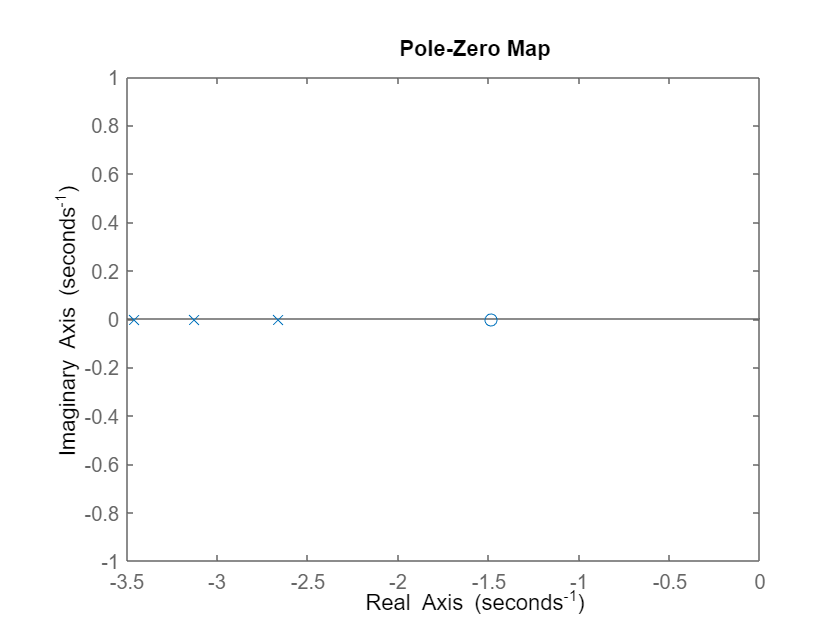

% Plotting the Zeros and Poles Location
pzplot(sys);

A minimum-phase system is a type of linear time-invariant system whose transfer function has all its poles and zeros in the left-half of the complex s-plane. As illustrated before, the system is minimum-phase since all its poles and zeros are located in the LHP.

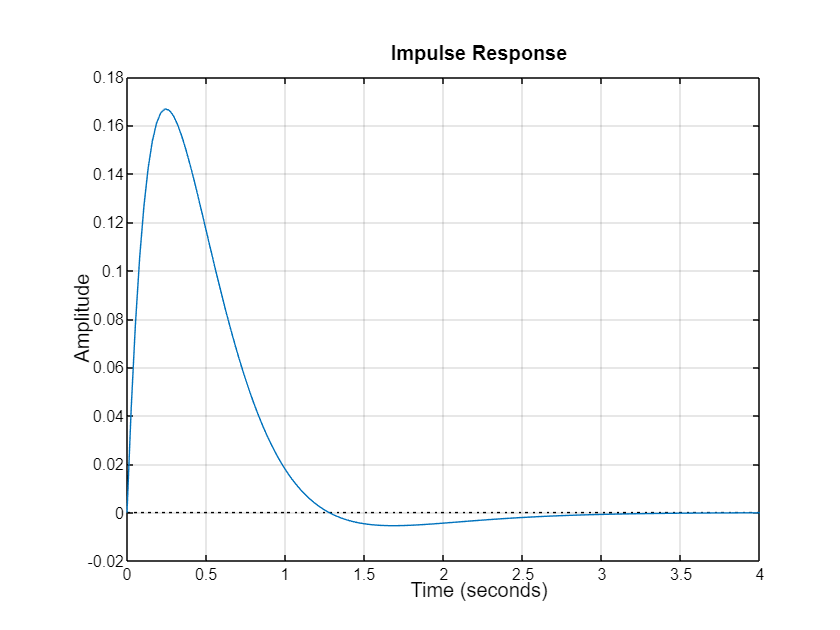

% Plotting System's Responses
%subplot(3,1,1);

plotoptions = timeoptions;
plotoptions.Grid = 'on';
plotoptions.Title.FontSize = 10;
plotoptions.Title.FontWeight = 'bold';
plotoptions.XLabel.FontSize = 10;
plotoptions.YLabel.FontSize = 10;

bodeopts = bodeoptions;
bodeopts.Grid = 'on';
bodeopts.Title.FontSize = 10;
bodeopts.Title.FontWeight = 'bold';
bodeopts.XLabel.FontSize = 10;
bodeopts.YLabel.FontSize = 10;

figure;
impulse(sys,4,plotoptions);
title('Impulse Response');

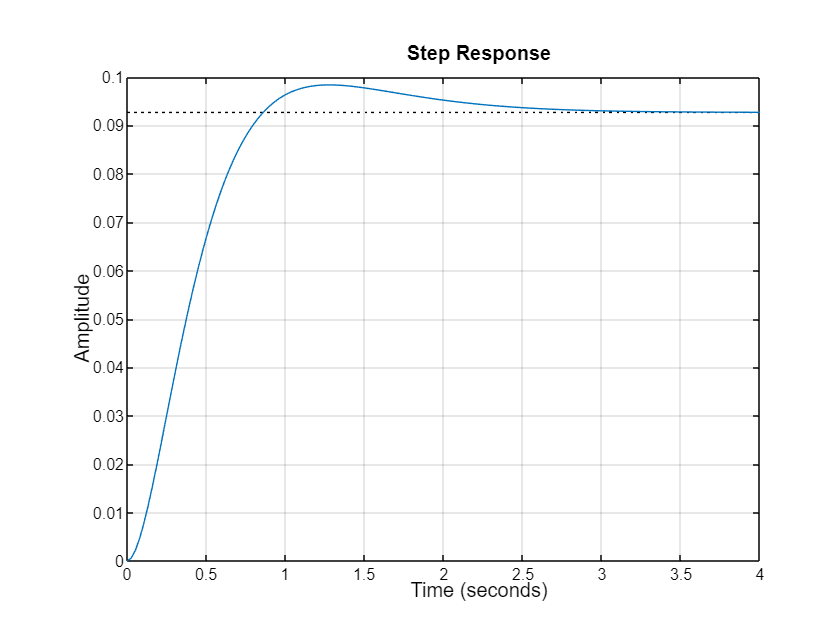

%subplot(3,1,2);

figure;
step(sys,4,plotoptions);
title('Step Response');

sysinfo = stepinfo(sys)

sysinfo = struct with fields:
         RiseTime: 0.5627
    TransientTime: 2.1762
     SettlingTime: 2.1762
      SettlingMin: 0.0842
      SettlingMax: 0.0984
        Overshoot: 6.1385
       Undershoot: 0
             Peak: 0.0984
         PeakTime: 1.2804


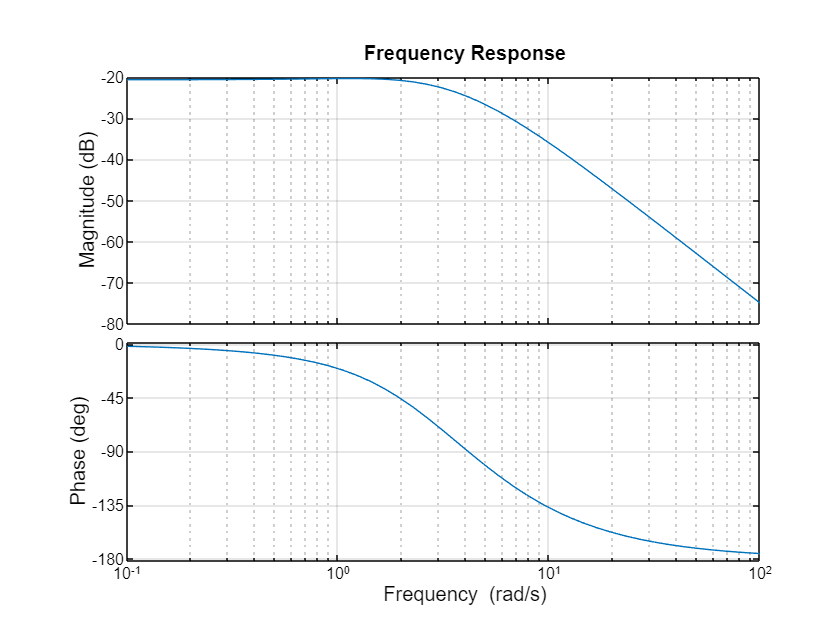

%subplot(3,1,3);

figure;
bode(sys, bodeopts);
title('Frequency Response');

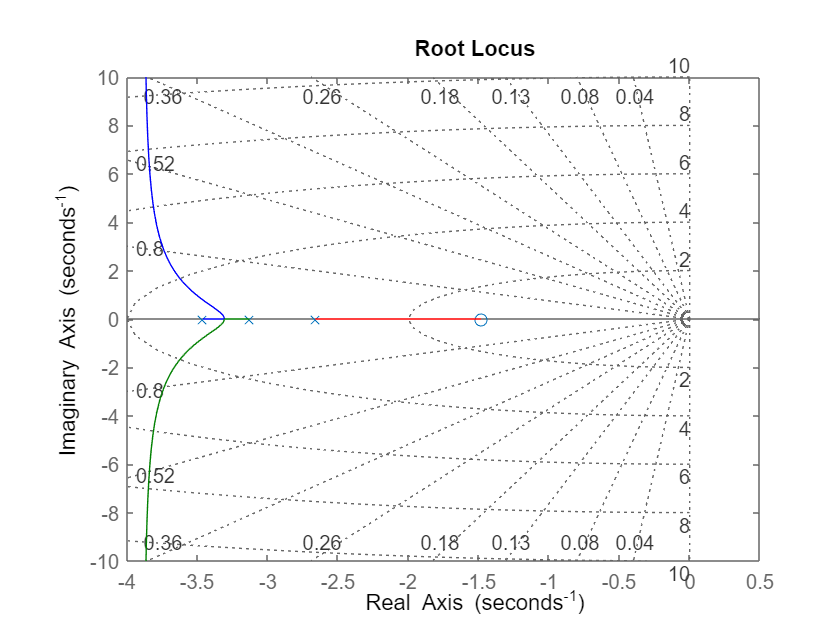


figure;
rlocus(sys);
grid on;

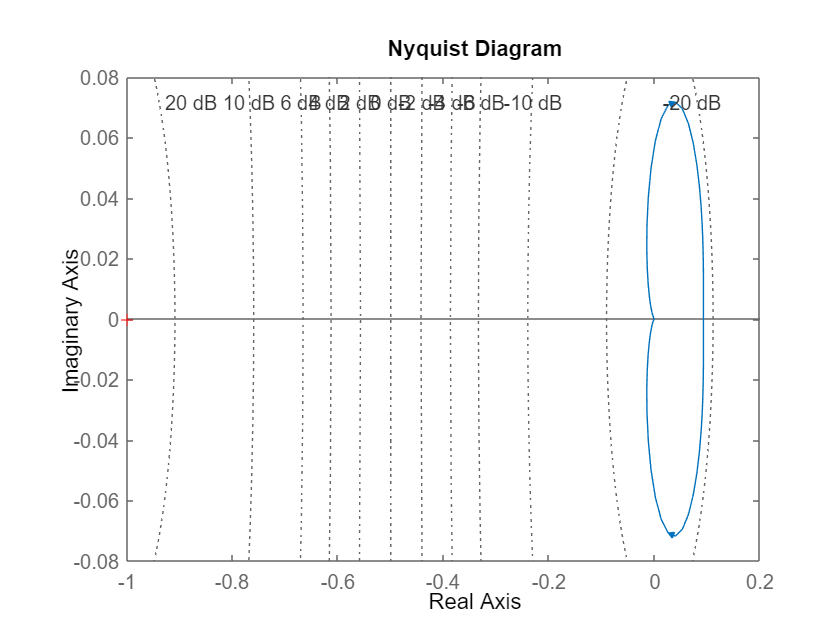


figure;
nyquistplot(sys);
grid on;

To provide a detailed analysis of the system's characteristics, we can look at the system's impulse response, step response, and frequency response.

**2.**    Obtain a state-space representation for the system.

The diagonal canonical form simplifies eigenvalue analysis and allows for reduced order representation with physical interpretation, making it a useful tool for expert analysis and controller design of proper or strictly proper systems. It's worth noting that there is no unique representation for the system, but the diagonal form provides a powerful and widely-used approach.

% Calculating the residues in partial fraction expansion
[residues,~,~] = residue(num, den)

residues =   -13.4512
   19.1417
   -5.6904


Modal Form State-Space Representation:

% Obtaining diagonal representation
A = diag(sys_poles);
B = [1; 1; 1];
C = residues';
D = 0;

Additionally, MATLAB provides a variety of built-in functions and tools for analyzing and designing control systems. One such tool is the ability to obtain a state-space representation for a transfer function. This can be achieved using the *tf2ss* or *canon* functions.

% state-space representation using tf2ss
% [A, B, C, D] = tf2ss(num, den);

% obtaining modal canonical form using canon
% sys_ss = canon(sys, "companion")

% Concluding the state-space equations
sys_modal = ss(A, B, C, D)

sys_modal =
 
  A = 
           x1      x2      x3
   x1   -3.46       0       0
   x2       0  -3.129       0
   x3       0       0  -2.662
 
  B = 
       u1
   x1   1
   x2   1
   x3   1
 
  C = 
           x1      x2      x3
   y1  -13.45   19.14   -5.69
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



**3.**    Investigate the controllability and observability of the obtained state-space representation. Is it possible to design a state feedback controller and an observer for this representation? If the obtained state-space representation is uncontrollable, separate it into controllable and uncontrollable subsystems. Similarly, if the obtained state-space representation is unobservable, separate it into observable and unobservable subsystems.

%   A dynamic system is said to be controllable if it is 
%   possible to apply control signals that drive the system to 
%   any state within a finite amount of time.
%       CO = CTRB(A,B) returns: 
%               the controllability matrix [B AB A^2B ...]

Co = ctrb(A, B)

Co =     1.0000   -3.4599   11.9707
    1.0000   -3.1285    9.7877
    1.0000   -2.6616    7.0842



%   A dynamic system is said to be observable if all its states 
%   can be known from the output of the system.
%       OB = OBSV(A,C) returns: 
%               the observability matrix [C; CA; CA^2 ...]

Ob = obsv(A, C)

Ob =   -13.4512   19.1417   -5.6904
   46.5395  -59.8852   15.1457
 -161.0203  187.3522  -40.3120



%   Alternatively, we could calculate the controllability and 
%   observability matrices directly instead of using built-in 
%   MATLAB functions. However, this approach may require more 
%   specialized knowledge. 
%
%       Co = [B, A*B, A^2*B]
%       Ob = [C; C*A; C*A^2]

rank_co = rank(Co);
rank_ob = rank(Ob);
isControllable = (rank(Co) == nStates);
isObserable = (rank(Ob) == nStates);

Based on the analysis of the controllability and observability matrices, we can conclude that the system is both *fully controllable* and *fully observable*. The controllability matrix is full rank, which means that there exists a control input that can be applied to the system to drive it to any desired state. Similarly, the observability matrix is full rank, which means that the internal states of the system can be estimated accurately from its outputs. The fact that both matrices have a full rank indicates that the system can be fully controlled and monitored using its inputs and outputs, respectively. This is a desirable property for a system, as it allows for precise control and monitoring of its behavior.

**4.**    If the obtained state-space representation is not minimal, obtain a minimal state-space representation for the system.

A state-space representation is said to be minimal if its state matrix A has a Jordan form containing as many Jordan blocks as the number of state variables. Therefore, if the system matrix A of a state-space representation has a Jordan form that satisfies this condition, then the state-space representation is minimal and there is no need for further modifications. This implies that the system has been represented with the smallest possible number of state variables that fully capture its dynamics, which can lead to more efficient and accurate analysis and control design. 

% Obtaining the jordan form
[V, J] = jordan(A)

V =      1     0     0
     0     1     0
     0     0     1


J =    -3.4599         0         0
         0   -3.1285         0
         0         0   -2.6616



% evaluating the eigenvalues of the system
[eigvectors, eigvalues] = eig(A)

eigvectors =      1     0     0
     0     1     0
     0     0     1


eigvalues =    -3.4599         0         0
         0   -3.1285         0
         0         0   -2.6616


Thus, according to the state matrix A the obtained state-space representation is *minimal*.

**5.**    Plot the open-loop system's step response (if stable) for a unit step input and arbitrary initial conditions.

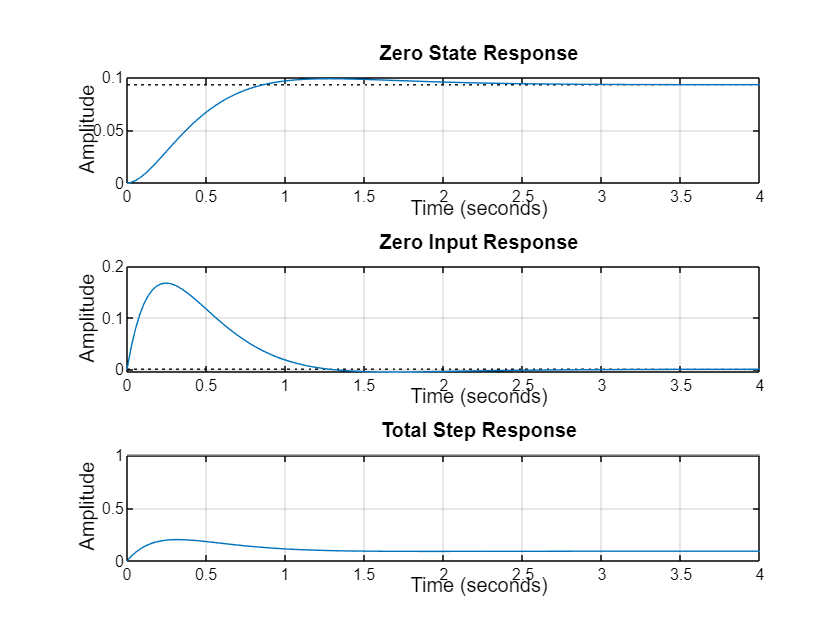

tFinal = 4;
t = 0:0.01:tFinal;      % time vector t = [0 ~ tFinal]
u = ones(size(t));      % step input u(t) = 1; for t>0
x0 = [1 1 1];           % arbitrary initial conditions

figure;
subplot(3,1,1);
step(sys_modal, tFinal, plotoptions);
title('Zero State Response');
subplot(3,1,2);
initial(sys_modal, x0, tFinal, plotoptions)
title('Zero Input Response');
subplot(3,1,3);
lsim(sys_modal, u, t, x0, plotoptions);
title('Total Step Response');

**6.**    Simulate the open-loop system using the obtained state-space representation and a negative unity feedback loop. Plot the closed-loop system's step response and calculate its poles and zeros. Provide a comprehensive analysis of the closed-loop system's characteristics.

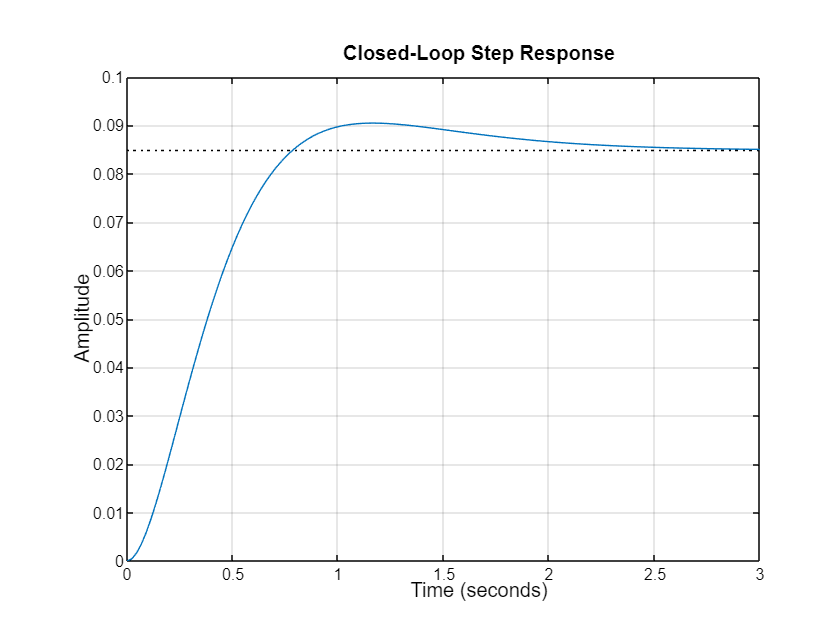

% Negative feedback gain
K = 1;

% Negative unity feedback loop
sys_cl = feedback(sys_modal, K);
g_cl = sys / (1 + (K * sys));

% Plot the closed-loop system's step response
figure;
step(sys_cl, plotoptions);
title('Closed-Loop Step Response');

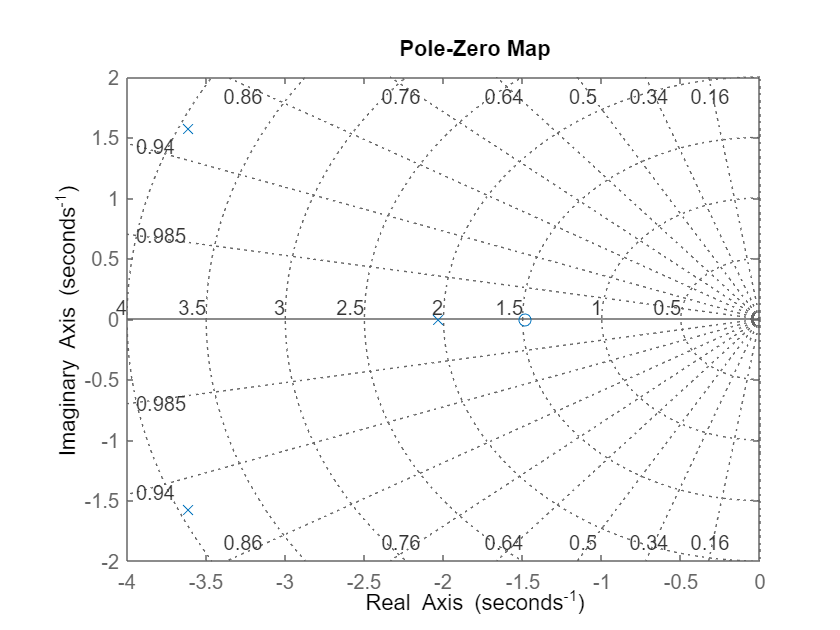


% Poles and Zeros of the closed-loop system
poles_cl = pole(sys_cl);
zeros_cl = zero(sys_cl);

pzmap(sys_cl);
grid on;

**7.**    Design a state feedback controller for the system such that its poles are placed at some desired locations on the left-hand side of the jω-axis. Plot the closed-loop system's step response, state variables, and control signal. Finally, compare the poles and zeros of the closed-loop system with those of the open-loop system. Perform this step for both far and close pole placements and compare the control signal and state feedback gain in both cases.

% Controllable Canonical Form
[A, B, C, D] = tf2ss(num, den);
sys_controllable = ss(A, B, C, D)

sys_controllable =
 
  A = 
           x1      x2      x3
   x1   -9.25  -28.36  -28.81
   x2       1       0       0
   x3       0       1       0
 
  B = 
       u1
   x1   1
   x2   0
   x3   0
 
  C = 
         x1    x2    x3
   y1     0   1.8  2.67
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.




% Define the desired poles
p_desired_close = [-5-4i, -5+4i, -1.5];
p_desired_far = [-25, -20, -15];

% Compute the feedback gain matrix
K_close = place(A, B, p_desired_close)

K_close =     2.2500   27.6400   32.6900


K_far = place(A, B, p_desired_far)

K_far = 1.0e+03 *

    0.0508    1.1466    7.4712



% Verify the pole placement
p_close = eig(A - B*K_close)

p_close =   -5.0000 + 4.0000i
  -5.0000 - 4.0000i
  -1.5000 + 0.0000i


p_far = eig(A - B*K_far)

p_far =   -25.0000
  -20.0000
  -15.0000


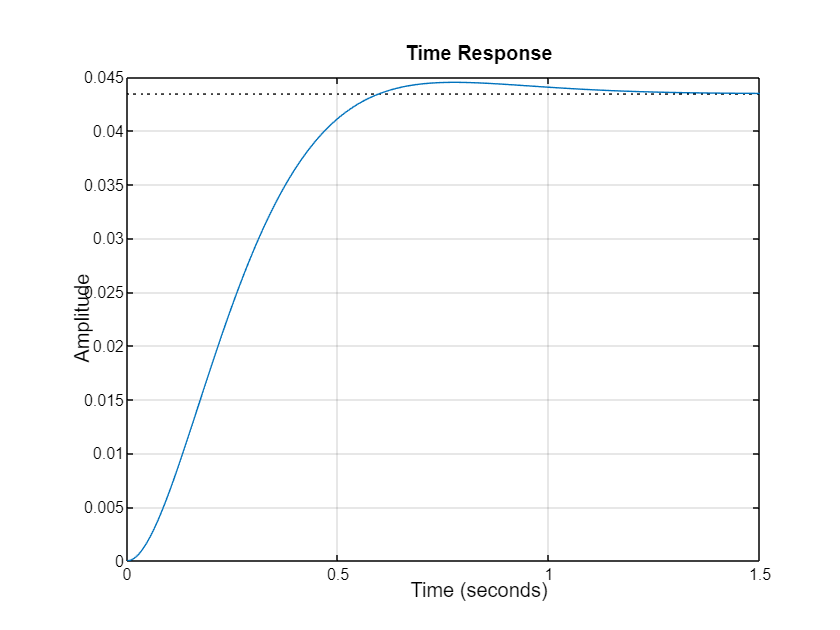


% Define the closed-loop system with state feedback
fb_close = ss(A - B*K_close, B, C, D);
fb_far = ss(A - B*K_far, B, C, D);

% Plot the closed-loop system's step response
figure;
step(fb_close, plotoptions);

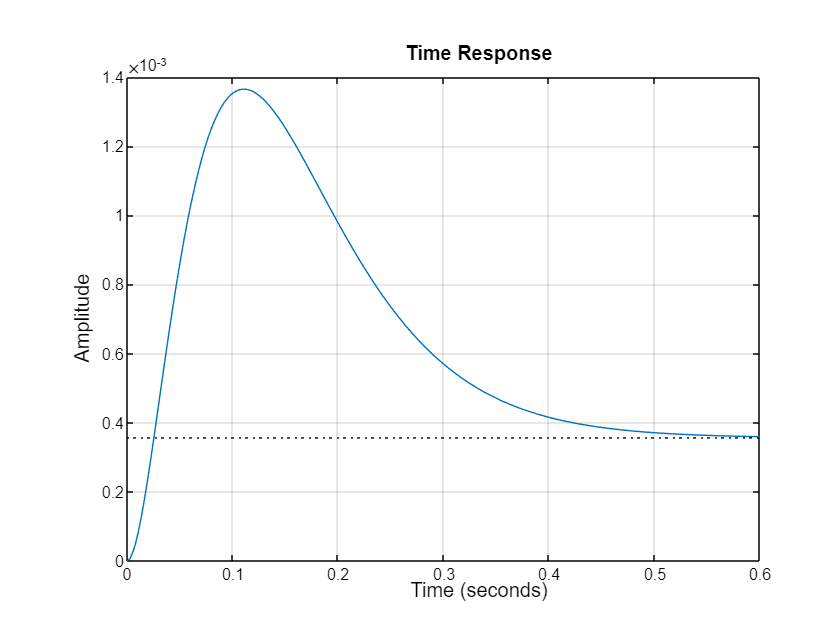


figure;
step(fb_far, plotoptions);


% Compare the step responses
stepinfo(sys_controllable)

ans = struct with fields:
         RiseTime: 0.5627
    TransientTime: 2.1762
     SettlingTime: 2.1762
      SettlingMin: 0.0842
      SettlingMax: 0.0984
        Overshoot: 6.1385
       Undershoot: 0
             Peak: 0.0984
         PeakTime: 1.2804


stepinfo(fb_close)

ans = struct with fields:
         RiseTime: 0.3680
    TransientTime: 0.9097
     SettlingTime: 0.9097
      SettlingMin: 0.0393
      SettlingMax: 0.0445
        Overshoot: 2.5081
       Undershoot: 0
             Peak: 0.0445
         PeakTime: 0.7737


stepinfo(fb_far)

ans = struct with fields:
         RiseTime: 0.0171
    TransientTime: 0.4791
     SettlingTime: 0.5527
      SettlingMin: 3.3720e-04
      SettlingMax: 0.0014
        Overshoot: 283.3890
       Undershoot: 0
             Peak: 0.0014
         PeakTime: 0.1105


stepinfo(sys_cl)

ans = struct with fields:
         RiseTime: 0.5157
    TransientTime: 2.0355
     SettlingTime: 2.0355
      SettlingMin: 0.0768
      SettlingMax: 0.0905
        Overshoot: 6.6718
       Undershoot: 0
             Peak: 0.0905
         PeakTime: 1.1560


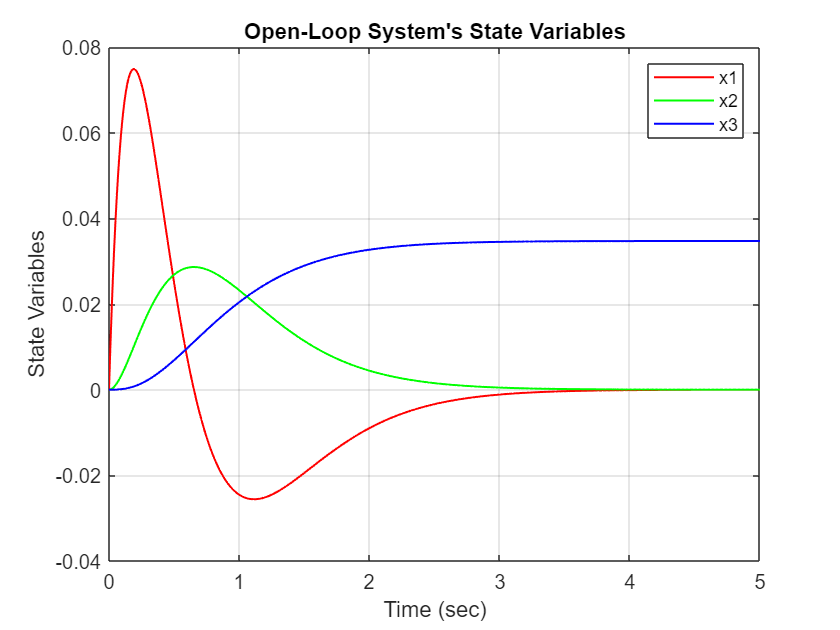


% Plot the state variables
tFinal = 5;
t = 0:0.01:tFinal;      % time vector t = [0 ~ tFinal]
u = ones(size(t));      % step input u(t) = 1; for t>0
x0 = [0; 0; 0];         % zero state initial condition

% [~, ~, x] = lsim(sys_modal, u, t, x0);
[~, ~, x] = lsim(sys_controllable, u, t, x0);

figure;
plot(t, x(:,1), 'r', t, x(:,2), 'g', t, x(:,3), 'b', LineWidth=1);
title("Open-Loop System's State Variables");
legend('x1', 'x2', 'x3');
xlabel('Time (sec)');
ylabel('State Variables');
grid on;

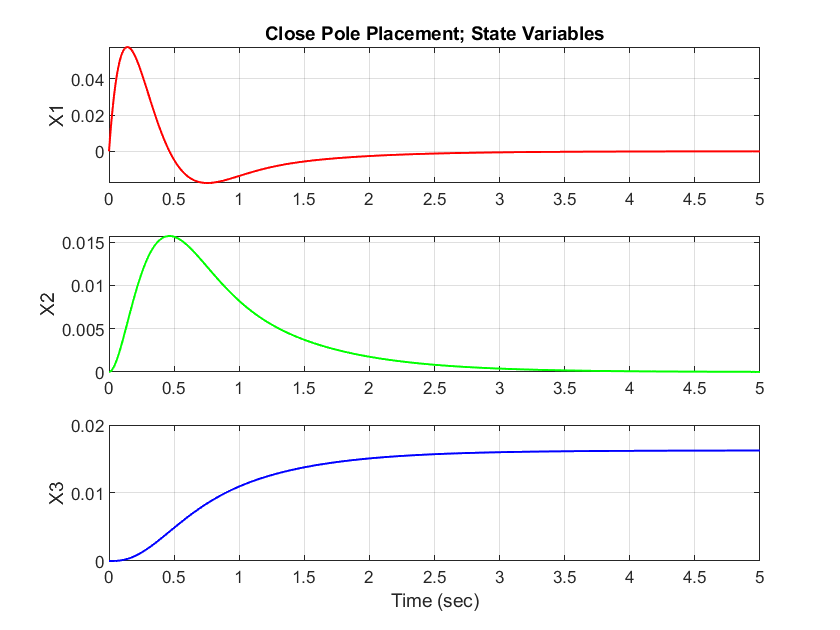


[~, ~, x_close] = lsim(fb_close, u, t, x0);

figure;
subplot(3,1,1);
plot(t, x_close(:,1),'r', LineWidth=1);
title("Close Pole Placement; State Variables");
ylabel('X1');
grid on;

subplot(3,1,2);
plot(t, x_close(:,2),'g', LineWidth=1);
ylabel('X2');
grid on;

subplot(3,1,3);
plot(t, x_close(:,3),'b', LineWidth=1);
xlabel('Time (sec)');
ylabel('X3');
grid on;

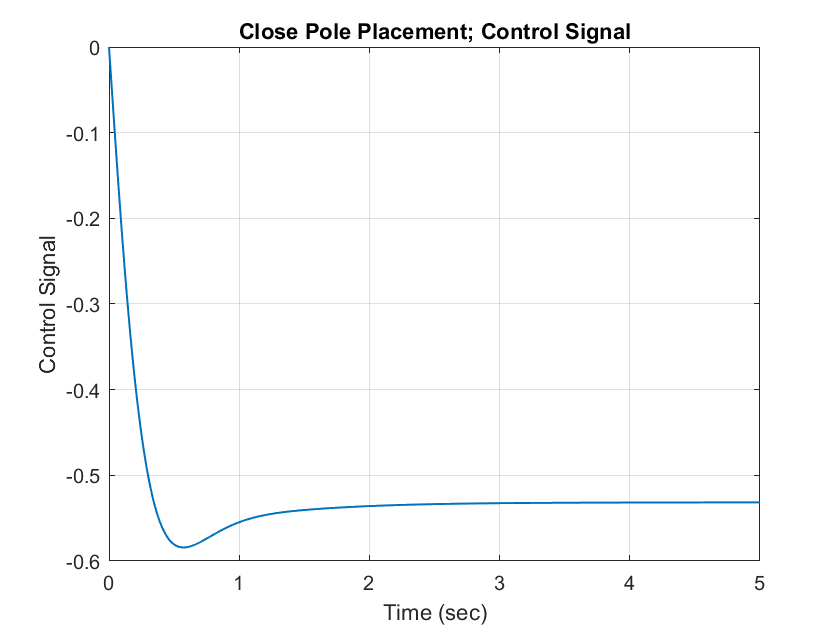


figure;
plot(t, -K_close*x_close', LineWidth=1);
title("Close Pole Placement; Control Signal");
xlabel('Time (sec)');
ylabel('Control Signal');
grid on;

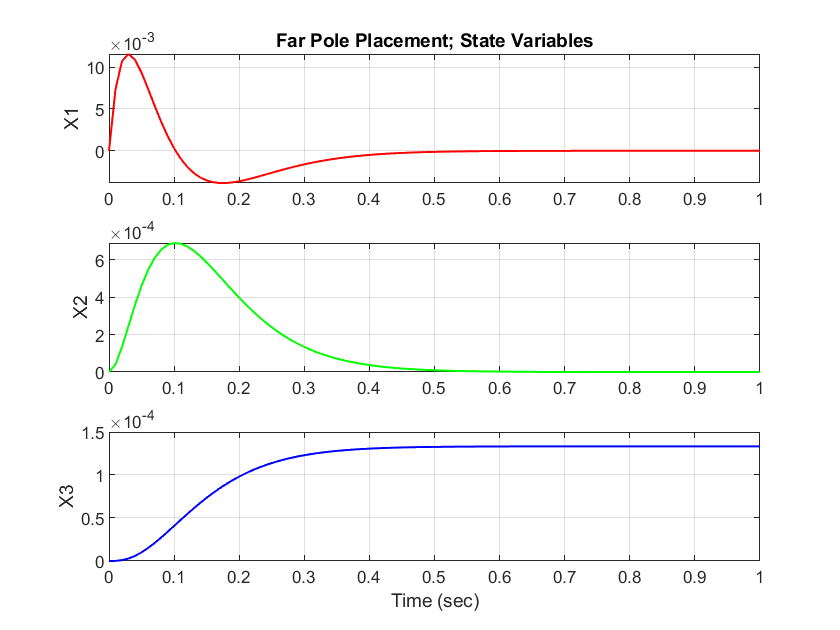


tFinal = 1;
t = 0:0.01:tFinal;      % time vector t = [0 ~ tFinal]
u = ones(size(t));      % step input u(t) = 1; for t>0
x0 = [0; 0; 0];         % zero state initial condition

[~, ~, x_far] = lsim(fb_far, u, t, x0);

figure;
subplot(3,1,1);
plot(t, x_far(:,1),'r', LineWidth=1);
title("Far Pole Placement; State Variables");
ylabel('X1');
grid on;

subplot(3,1,2);
plot(t, x_far(:,2),'g', LineWidth=1);
ylabel('X2');
grid on;

subplot(3,1,3);
plot(t, x_far(:,3),'b', LineWidth=1);
xlabel('Time (sec)');
ylabel('X3');
grid on;

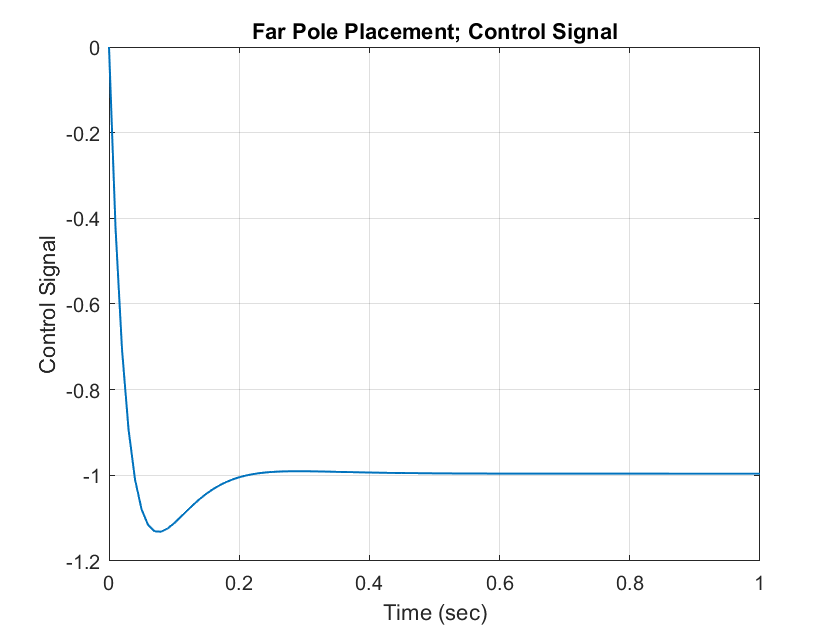


figure;
plot(t, -K_far*x_far', LineWidth=1);
title("Far Pole Placement; Control Signal");
xlabel('Time (sec)');
ylabel('Control Signal');
grid on;

**8.    **Design a static tracker for the obtained state-space representation.

% Calculate the static scaling factor
desired_output = 1;
n_bar = desired_output / (C*inv(-(A-B*K_close))*B)

n_bar = 23.0337

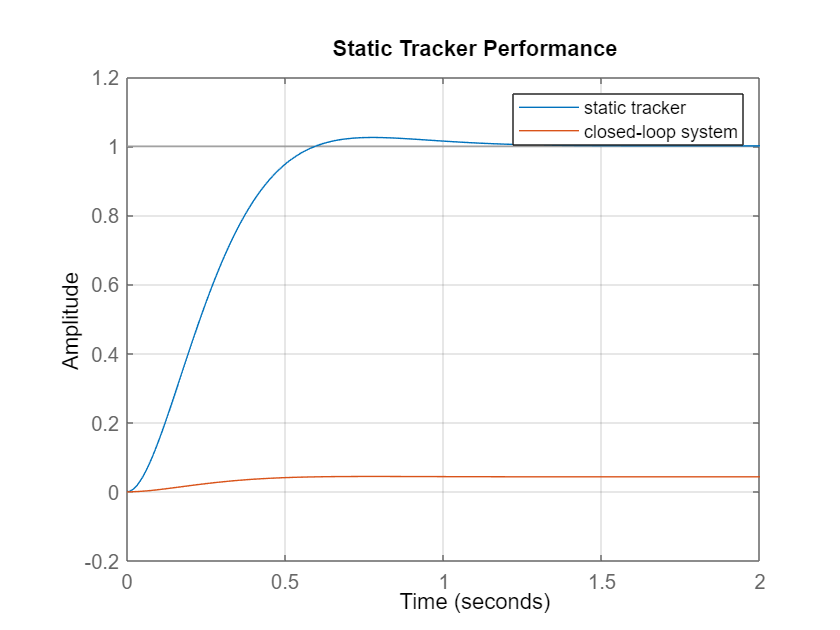


tFinal = 2;
t = 0:0.01:tFinal;      % time vector t = [0 ~ tFinal]
u = ones(size(t));      % step input u(t) = 1; for t>0
x0 = [0; 0; 0];         % zero state initial condition

figure;
hold on;
lsim(fb_close, n_bar*u, t, x0);
lsim(fb_close, u, t, x0);
legend('static tracker','closed-loop system')
title('Static Tracker Performance');
grid on;

**9.**    Design an integral (robust) tracker for the obtained state-space representation.

% Check the condition to design the tracker
rank_aug = rank([B, A; 0, -C])

rank_aug = 4


n = 3;  % states
m = 1;  % inputs
p = 1;  % outputs

isTrackable = (rank_aug == n+m);

% Obtain the augmented state-space model
A_aug = [A, zeros(n, m); -C, zeros(p, m)];
B_aug = [B; zeros(m, m)];
C_aug = [C, zeros(p, m)];
D_aug = 0;

B_r = [zeros(n, m); ones(p, m)];

% Construct the state-space representation
sys_aug = ss(A_aug, B_aug, C_aug, D_aug)

sys_aug =
 
  A = 
           x1      x2      x3      x4
   x1   -9.25  -28.36  -28.81       0
   x2       1       0       0       0
   x3       0       1       0       0
   x4       0    -1.8   -2.67       0
 
  B = 
       u1
   x1   1
   x2   0
   x3   0
   x4   0
 
  C = 
         x1    x2    x3    x4
   y1     0   1.8  2.67     0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.




% Desired pola placement
p_desired_tracker = [p_desired_close, -10];
K_tracker = place(A_aug, B_aug, p_desired_tracker)

K_tracker =    12.2500  142.6400  178.0833 -230.3371



% Verify the pole placement
eig(A_aug - B_aug*K_tracker)

ans =  -10.0000 + 0.0000i
  -5.0000 + 4.0000i
  -5.0000 - 4.0000i
  -1.5000 + 0.0000i


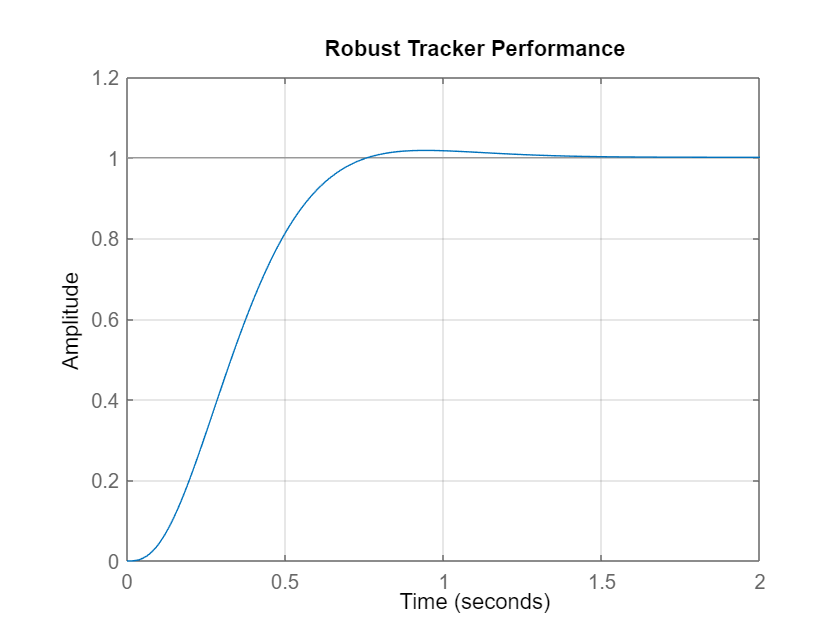


% Obtain the robust tracker state-space model
sys_tracker = ss(A_aug - B_aug*K_tracker, B_r, C_aug, D_aug);

tFinal = 2;
t = 0:0.01:tFinal;      % time vector t = [0 ~ tFinal]
r = ones(size(t));      % step input r(t) = 1; for t>0
x0 = [0; 0; 0; 0];      % zero state initial condition

figure;
lsim(sys_tracker, r, t, x0);
title('Robust Tracker Performance');
grid on;

stepinfo(sys_tracker)

ans = struct with fields:
         RiseTime: 0.4335
    TransientTime: 0.6992
     SettlingTime: 0.6992
      SettlingMin: 0.9034
      SettlingMax: 1.0180
        Overshoot: 1.8001
       Undershoot: 0
             Peak: 1.0180
         PeakTime: 0.9395


**10.**    Compare and analyze the performance of the two designed tracking controllers based on the following criteria:

- Tracking performance

- Robustness in the presence of model parameter variations

- Closed-loop system performance under constant disturbances.

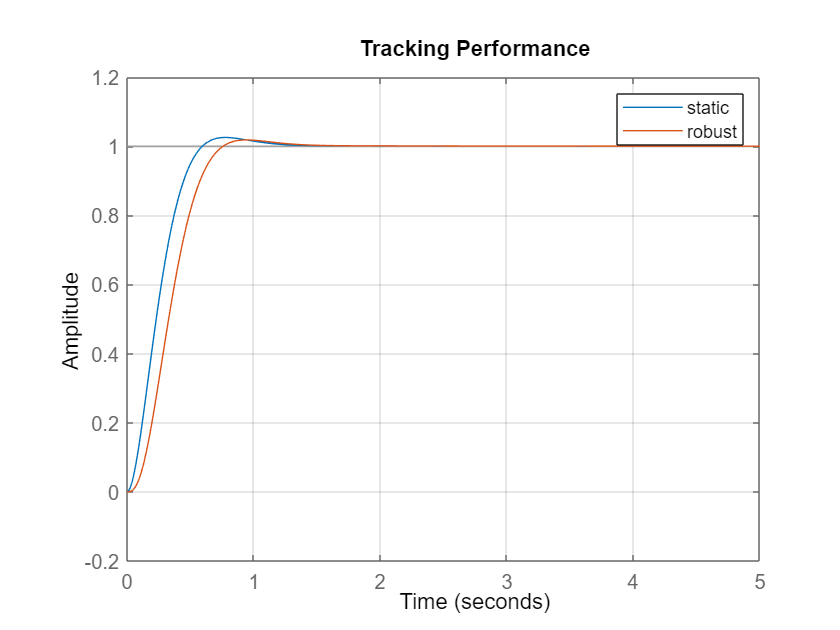

% ----------------------------------------------------
% TRACKING PERFORMANCE -------------------------------

tFinal = 5;
t = 0:0.01:tFinal;      % time vector t = [0 ~ tFinal]
r = ones(size(t));      % step input r(t) = 1; for t>0

figure;
hold on;
lsim(fb_close, n_bar*r, t, [0 0 0]);
lsim(sys_tracker, r, t, [0 0 0 0]);
legend('static','robust');
title("Tracking Performance");
grid on;

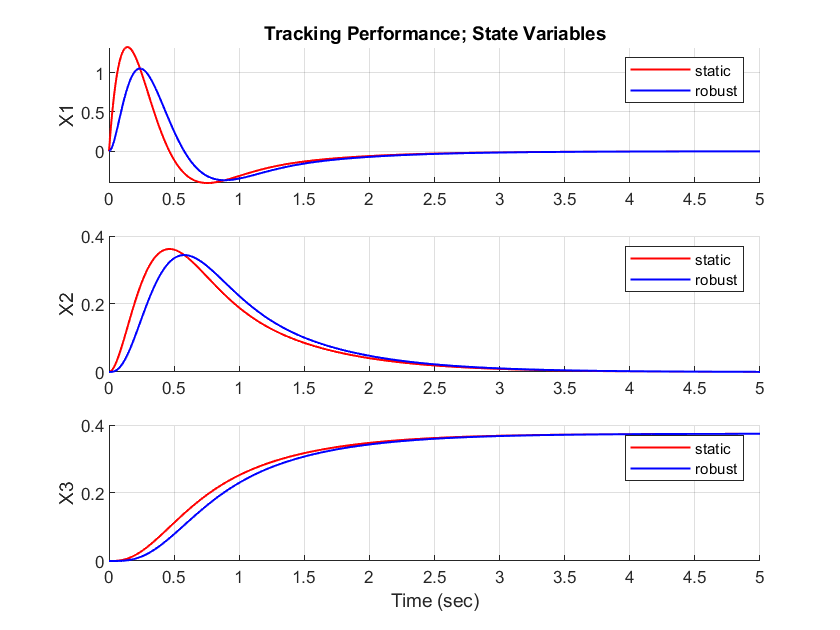


[~,~,x_static] = lsim(fb_close, n_bar*r, t, [0 0 0]);
[~,~,x_robust] = lsim(sys_tracker, r, t, [0 0 0 0]);

figure;
subplot(3,1,1);
hold on;
plot(t, x_static(:,1),'r', LineWidth=1);
plot(t, x_robust(:,1),'b', LineWidth=1);
legend('static','robust');
title("Tracking Performance; State Variables");
ylabel('X1');
grid on;

subplot(3,1,2);
hold on;
plot(t, x_static(:,2),'r', LineWidth=1);
plot(t, x_robust(:,2),'b', LineWidth=1);
legend('static','robust');
ylabel('X2');
grid on;

subplot(3,1,3);
hold on;
plot(t, x_static(:,3),'r', LineWidth=1);
plot(t, x_robust(:,3),'b', LineWidth=1);
legend('static','robust');
xlabel('Time (sec)');
ylabel('X3');
grid on;

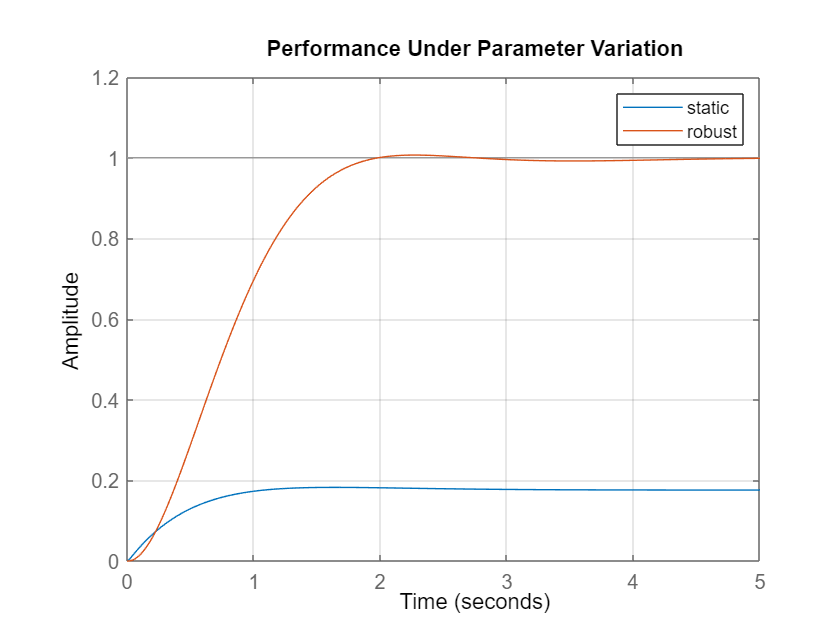


% ----------------------------------------------------
% SYSTEM PARAMETER VARIATION -------------------------

A_var = A + 10*[A(1,:); zeros(n-1,n)];
% A_var = Ac + [Ac(1,1)   0     0     ; zeros(n-1,n)];
% A_var = Ac + [   0   Ac(1,2)  0     ; zeros(n-1,n)];
% A_var = Ac + [   0      0   Ac(1,3) ; zeros(n-1,n)];

% new robust tracker model
A_aug_var = [A_var, zeros(n, m); -C, zeros(p, m)];
sys_tracker_var = ss(A_aug_var - B_aug*K_tracker, B_r, C_aug, D_aug);

% new static tracker model
fb_close_var = ss(A_var - B*K_close, B, C, D);

figure;
hold on;
lsim(fb_close_var, n_bar*r, t, [0 0 0]);
lsim(sys_tracker_var, r, t, [0 0 0 0]);
legend('static','robust');
title("Performance Under Parameter Variation");
grid on;

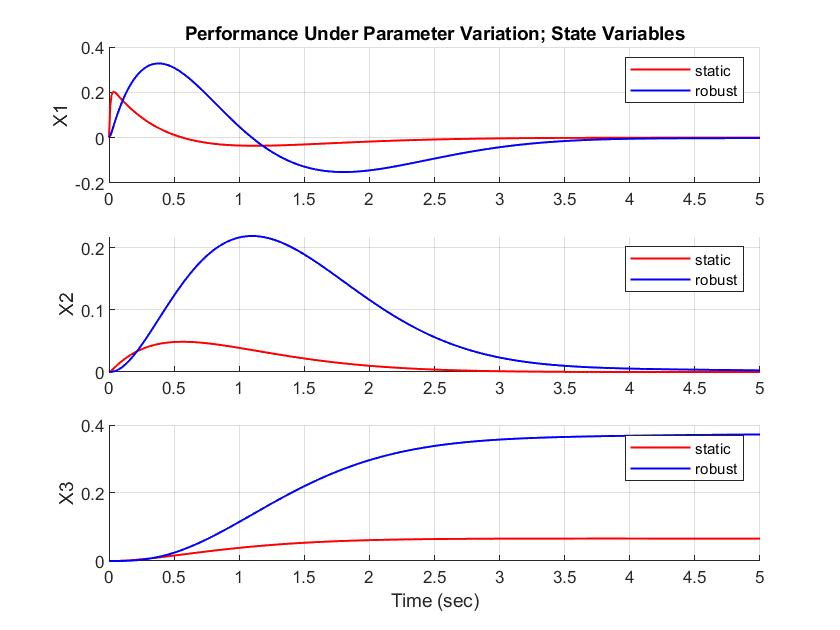


[~,~,x_static] = lsim(fb_close_var, n_bar*r, t, [0 0 0]);
[~,~,x_robust] = lsim(sys_tracker_var, r, t, [0 0 0 0]);

figure;
subplot(3,1,1);
hold on;
plot(t, x_static(:,1),'r', LineWidth=1);
plot(t, x_robust(:,1),'b', LineWidth=1);
legend('static','robust');
title("Performance Under Parameter Variation; State Variables");
ylabel('X1');
grid on;

subplot(3,1,2);
hold on;
plot(t, x_static(:,2),'r', LineWidth=1);
plot(t, x_robust(:,2),'b', LineWidth=1);
legend('static','robust');
ylabel('X2');
grid on;

subplot(3,1,3);
hold on;
plot(t, x_static(:,3),'r', LineWidth=1);
plot(t, x_robust(:,3),'b', LineWidth=1);
legend('static','robust');
xlabel('Time (sec)');
ylabel('X3');
grid on;


% under bias and constant disturbance

**11.**    Design a full-order observer for the obtained state-space representation. Determine the criterion for selecting the observer poles. Plot the state variables of the system and the estimation error. Choose two sets of slow and fast observer poles and design the corresponding full-order observers. Plot and compare the state variables of the original system and the estimated ones using both observers.

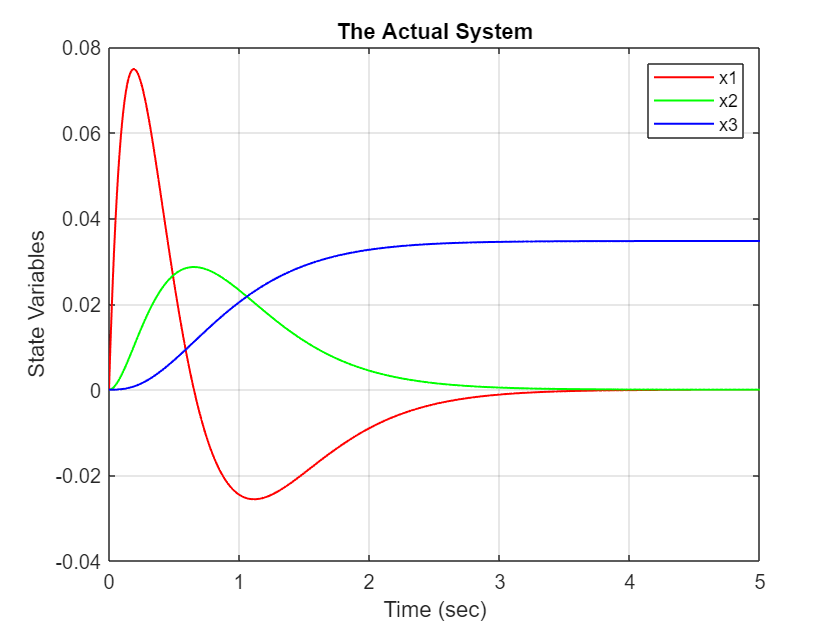

% Observer with fast poles
obs_poles_fast = 100*sys_poles;
L_fast = place(A', C', obs_poles_fast)';

A_obs_fast =    [     A         zeros(size(A))
                zeros(size(A))    A-L_fast*C ];
B_obs_fast =    [     B
                zeros(size(B)) ];
C_obs_fast =    [     C       zeros(size(C)) ];

% Obtain the state-space model
obs_fast = ss(A_obs_fast, B_obs_fast, C_obs_fast, 0);


% Observer with slow poles
obs_poles_slow = 10*sys_poles;
L_slow = place(A', C', obs_poles_slow)';

A_obs_slow =    [     A         zeros(size(A))
                zeros(size(A))    A-L_slow*C ];
B_obs_slow =    [     B
                zeros(size(B)) ];
C_obs_slow =    [     C       zeros(size(C)) ];

% Obtain the state-space model
obs_slow = ss(A_obs_slow, B_obs_slow, C_obs_slow, 0);


tFinal = 5;
t = 0:0.01:tFinal;      % time vector t = [0 ~ tFinal]
u = ones(size(t));      % step input u(t) = 1; for t>0

% Plot the state variables of the actual system
[~, ~, x] = lsim(sys_controllable, u, t, [0 0 0]);

figure;
plot(t, x(:,1), 'r', t, x(:,2), 'g', t, x(:,3), 'b', LineWidth=1);
title("The Actual System");
legend('x1', 'x2', 'x3');
xlabel('Time (sec)');
ylabel('State Variables');
grid on;

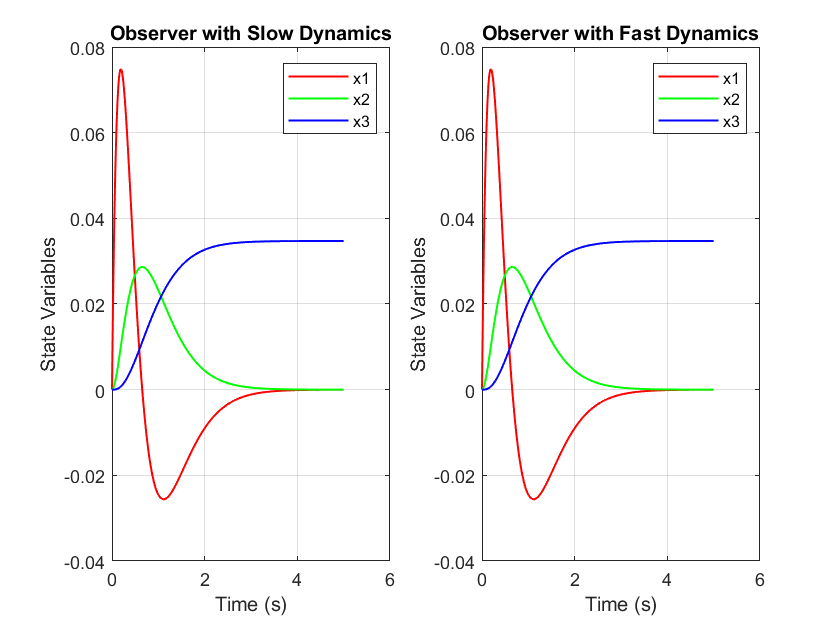


% Plot the state variables of the observers
[~, ~, x_fast] = lsim(obs_fast, u, t, [0 0 0 0 0 0]);
[~, ~, x_slow] = lsim(obs_slow, u, t, [0 0 0 0 0 0]);

figure;
subplot(1, 2, 2);
plot(t, x_fast(:,1), 'r', t, x_fast(:,2), 'g', t, x_fast(:,3), 'b', LineWidth=1);
legend('x1', 'x2', 'x3');
title('Observer with Fast Dynamics');
xlabel('Time (s)');
ylabel('State Variables');
grid on;

subplot(1, 2, 1);
plot(t, x_slow(:,1), 'r', t, x_slow(:,2), 'g', t, x_slow(:,3), 'b', LineWidth=1);
legend('x1', 'x2', 'x3');
title('Observer with Slow Dynamics');
xlabel('Time (s)');
ylabel('State Variables');
grid on;

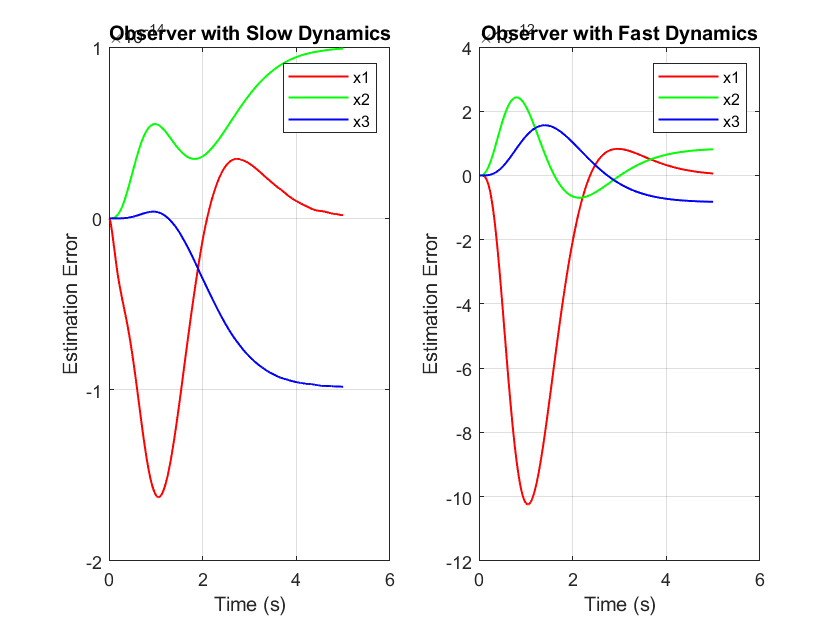


% Plot the estimation error of the observers
err_fast = [x(:,1)-x_fast(:,1), x(:,2)-x_fast(:,2), x(:,3)-x_fast(:,3)];
err_slow = [x(:,1)-x_slow(:,1), x(:,2)-x_slow(:,2), x(:,3)-x_slow(:,3)];

figure;
subplot(1, 2, 1);
plot(t, err_slow(:,1), 'r', t, err_slow(:,2), 'g', t, err_slow(:,3), 'b', LineWidth=1);
title('Observer with Slow Dynamics');
xlabel('Time (s)');
ylabel('Estimation Error');
legend('x1', 'x2', 'x3');
grid on;

subplot(1, 2, 2);
plot(t, err_fast(:,1), 'r', t, err_fast(:,2), 'g', t, err_fast(:,3), 'b', LineWidth=1);
title('Observer with Fast Dynamics');
xlabel('Time (s)');
ylabel('Estimation Error');
legend('x1', 'x2', 'x3');
grid on;

**12.**    Change one of the system parameters and use the same observer designed in the previous step to estimate the states of the modified system. Analyze the results.

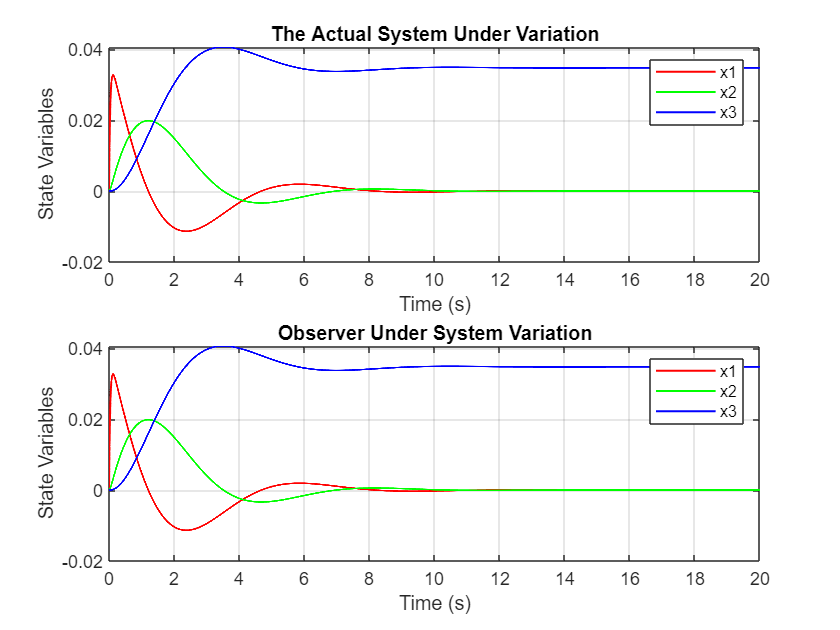

A_var = A + 2* [ A(1,1) zeros(1, n-1); zeros(n-1,n) ];

A_obs_var =    [     A_var          zeros(size(A_var))
                zeros(size(A_var))   A_var-L_fast*C ];
B_obs_var =    [      B
                zeros(size(B)) ];
C_obs_var =    [      C              zeros(size(C)) ];

obs_var = ss(A_obs_var, B_obs_var, C_obs_var, 0);

tFinal = 20;
t = 0:0.001:tFinal;
u = ones(size(t));

[~, ~, x_var] = lsim(ss(A_var,B,C,0), u, t, [0 0 0]);
[~, ~, x_obs_var] = lsim(obs_var, u, t, [0 0 0 0 0 0]);

err_var = [ x_var(:,1)-x_obs_var(:,1), ...
            x_var(:,2)-x_obs_var(:,2), ...
            x_var(:,3)-x_obs_var(:,3)];

figure;
subplot(2,1,1);
plot(t, x_var(:,1), 'r', t, x_var(:,2), 'g', t, x_var(:,3), 'b', LineWidth=1);
legend('x1', 'x2', 'x3');
title('The Actual System Under Variation');
xlabel('Time (s)');
ylabel('State Variables');
grid on;

subplot(2,1,2);
plot(t, x_obs_var(:,1), 'r', t, x_obs_var(:,2), 'g', t, x_obs_var(:,3), 'b', LineWidth=1);
legend('x1', 'x2', 'x3');
title('Observer Under System Variation');
xlabel('Time (s)');
ylabel('State Variables');
grid on;

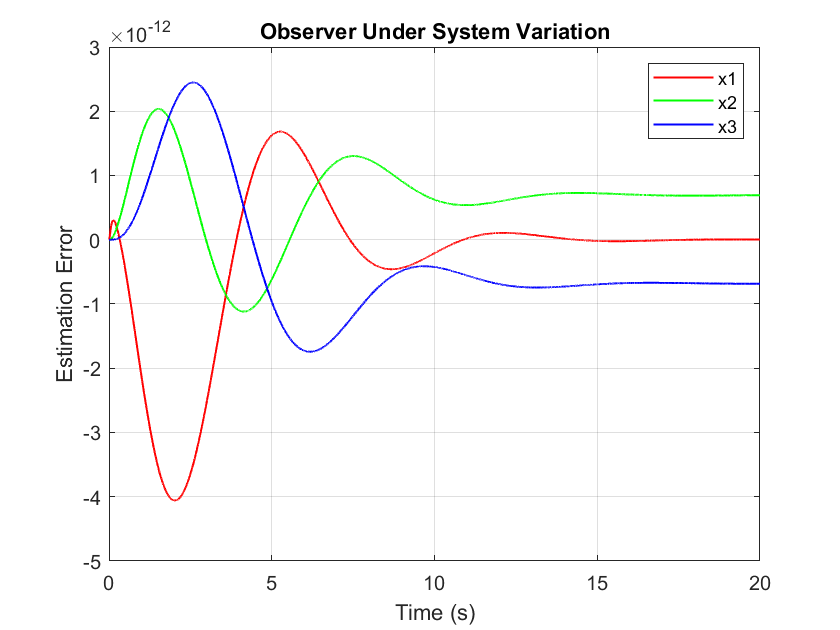

figure;
plot(t, err_var(:,1), 'r', t, err_var(:,2), 'g', t, err_var(:,3), 'b', LineWidth=1);
title('Observer Under System Variation');
xlabel('Time (s)');
ylabel('Estimation Error');
legend('x1', 'x2', 'x3');
grid on;

**13.**    Design a reduced-order observer for the obtained state-space representation. Plot the state variables of the system and the estimation error.

display(C);

C =          0    1.8000    2.6700


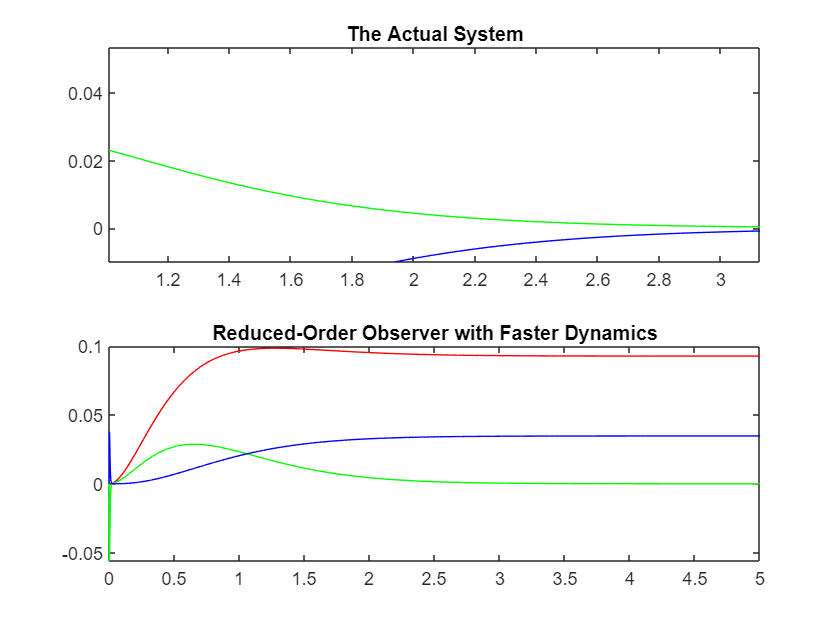

% Evaluate the value q
q = rank(C);

% Construct the R matrix
R = [   0   1   0   ;   
        1   0   0   ];

% P must be full-rank and invertible
P = [   C   ; 
        R   ];
% Verify the obtained P matrix
rank(P);
inv(P);

A_bar = P*A*inv(P);
B_bar = P*B;
C_bar = C*inv(P);
D_bar = 0;

sys_singular = ss(A_bar, B_bar, C_bar, D_bar);
sys_poles = pole(sys_singular);

% Decompose the system matrix A_bar 
A11 = A_bar(1:q, 1:q);
A12 = A_bar(1:q, q+1:n);
A21 = A_bar(q+1:n, 1:q);
A22 = A_bar(q+1:n, q+1:n);

% Decompose the input matrix B_bar 
B1 = B_bar(1:q, :);
B2 = B_bar(q+1:n, :);

% Desired Observer Poles
p_reduced_obs = 100*sys_poles(1:n-q, 1);

% Evaluate the obserever coefficients L
L_bar = place(A22', A12', p_reduced_obs)';

% C_red = A12;
% A_red = [A22-L_bar*A12]*[-L_bar eye(n-q)] - [(A22-L_bar*A12)*L_bar+(A21-L_bar*A11) zeros(2,2)];
% A_red_1 = A_red(:,1);
% A_red = A_red(1:end,2:end);
% B_red = B2-L_bar*B1;
% 
% sys_red = ss(A_red, B_red, C_red, 0);

tFinal = 5;
dt = 0.001;
t = 0:dt:tFinal;
u = ones(size(t));

% [y_bar, ~, x_bar] = lsim(sys_singular, u, t, [0 0 0]);
% [y_red, ~, x_red] = lsim(sys_red, u, t, [0 0]);
% y_bias = [0 0];
% for i = 2:size(y_bar)
%     y_bias = [y_bias ;((L_bar+A_red_1)*y_bar(i,1))'];
% end
% 
% x_red = x_red + y_bias;
% x_red = [y_bar x_red];
% 
% figure;
% subplot(2,1,1);
% plot(t, x_bar(:,1), 'r', t, x_bar(:,2), 'g', t, x_bar(:,3), 'b', LineWidth=1);
% legend('x1', 'x2', 'x3');
% title('The Actual System Under Variation');
% xlabel('Time (s)');
% ylabel('State Variables');
% grid on;
% 
% subplot(2,1,2);
% plot(t, x_red(:,1), 'r', t, x_red(:,2), 'g', t, x_red(:,3), 'b', LineWidth=1);
% legend('x2', 'x3');
% title('Observer Under System Variation');
% xlabel('Time (s)');
% ylabel('State Variables');
% grid on;

x_bar(:,1) = [0; 0; 0];
z(:,1) = [0; 0];


for k = 2:size(t,2)
    y_red(k) = C_bar * x_bar(:,k-1);
    x_bar(:,k) = x_bar(:, k-1) + dt*(A_bar* x_bar(:,k-1) + B_bar*1);
    z(:,k) = z(:,k-1) + dt*((A22 - L_bar*A12)*z(:,k-1) + ((A22 - L_bar*A12)*L_bar + (A21 - L_bar*A11))*y_red(k-1) + (B2-L_bar*B1)*1);
end

x_red = inv(P)*([[1 0 0 ];[L_bar eye(2)]])*[y_red; z];

figure();
subplot(2,1,1);
plot(t, x_bar(1,:), 'r', t, x_bar(2,:), 'g', t, x_bar(3,:), 'b');
title("The Actual System");

subplot(2,1,2)
plot(t, y_red, 'r', t, x_red(2,:), 'g', t, x_red(3,:), 'b')
title("Reduced-Order Observer with Faster Dynamics")


%Evaluate the estimated state variables
% x_bar_est = eye(n) + [ zeros(q, q)    zeros(q, n-q)  ;
%                         L_bar      zeros(n-q, n-q) ]
% Transform into the main model using singularity matrix P
% x_est = inv(P)*x_bar_est;

**14.**     Design a state feedback controller for the closed-loop system using the estimated states such that the poles are located on the left half of the jω-axis and the step response exhibits acceptable overshoot and settling time behavior. Plot the step response and the state variables of the system. Assume that the actual states are not available and only the estimated states can be used for state feedback. Consider a full-order observer for this question.

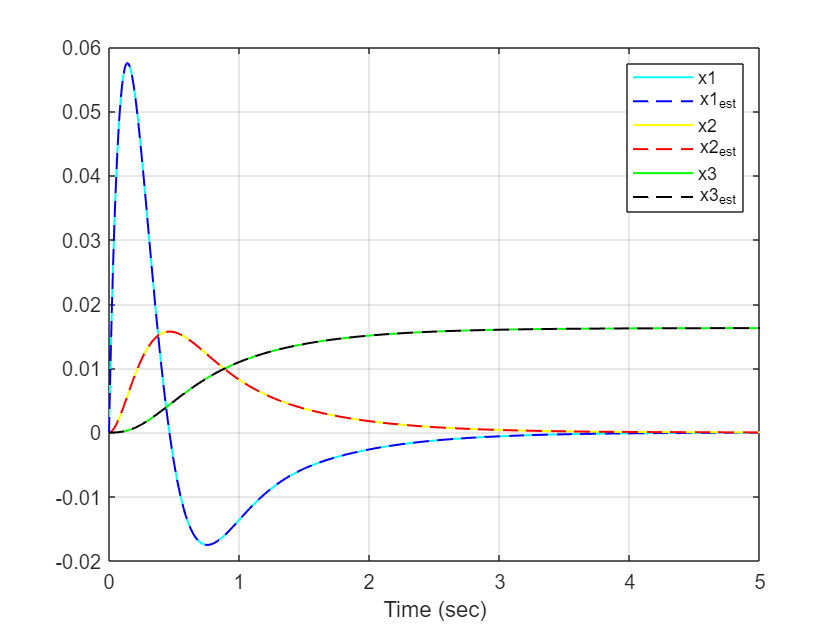

p_desired_regulator = [-5-4i, -5+4i, -1.5];
K = place(A, B, p_desired_regulator);

p_desired_observer = 10*p_desired_regulator;
L = place(A', C', p_desired_observer)';

A_reg = [   A-B*K          B*K;
        zeros(size(A))    A-L*C ];

B_reg = [     B;
        zeros(size(B)) ];

C_reg = [     C    zeros(size(C)) ];

t = 0:0.01:5;
x0 = [0 0 0];
[~,~,x_reg] = lsim(ss(A_reg,B_reg,C_reg,0),ones(size(t)),t,[x0 x0]);

n = 3;
e = x_reg(:,n+1:end);
x_reg = x_reg(:,1:n);
x_est = x_reg - e;

% Save state variables explicitly to aid in plotting
x1 = x_reg(:,1); x2 = x_reg(:,2); x3 = x_reg(:,3);
x1_est = x_est(:,1); x2_est = x_est(:,2); x3_est = x_est(:,3);

figure;
plot(t,x1,'-c',t,x1_est,'--b',t,x2,'-y',t,x2_est,'--r',t,x3,'-g',t,x3_est,'--k',LineWidth=1);
legend('x1','x1_{est}','x2','x2_{est}','x3','x3_{est}');
xlabel('Time (sec)');
grid on;

**15.**     Design a state feedback regulator with a reduced-order observer for the assumed system.

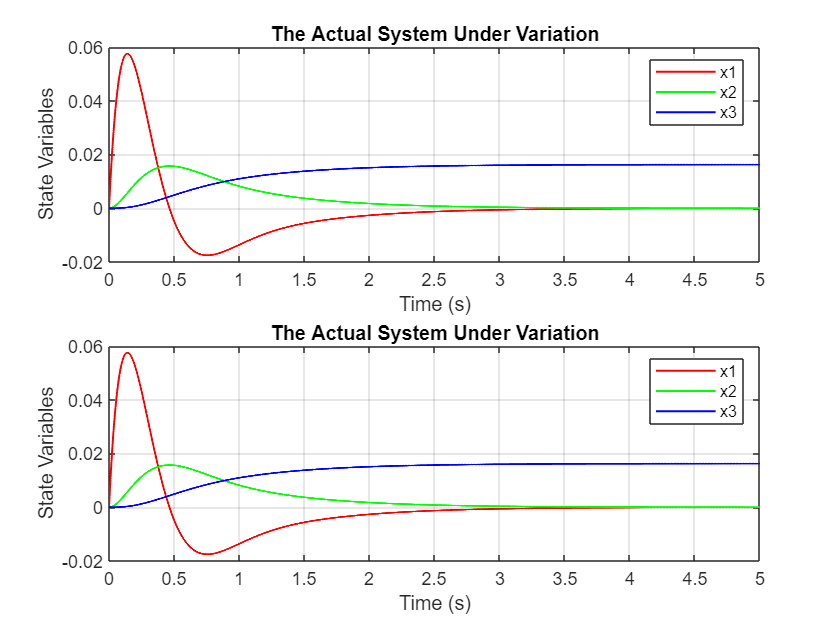

p_desired_regulator = [-5-4i, -5+4i, -1.5];
K = place(A, B, p_desired_regulator);

q = rank(C);
R = [   0   1   0   ;   
        1   0   0   ];
P = [   C   ; 
        R   ];

rank(P);
Q = inv(P);
Q1 = Q(1:3,1);
Q2 = Q(1:3,2:3);

A_bar = P*A*inv(P);
B_bar = P*B;
C_bar = C*inv(P);
D_bar = 0;

sys_singular = ss(A_bar, B_bar, C_bar, D_bar);

A11 = A_bar(1:q, 1:q);
A12 = A_bar(1:q, q+1:n);
A21 = A_bar(q+1:n, 1:q);
A22 = A_bar(q+1:n, q+1:n);

B1 = B_bar(1:q, :);
B2 = B_bar(q+1:n, :);

p_reduced_observer = 10*p_desired_regulator(1:n-q);
L_bar = place(A22', A12', p_reduced_observer)';

% Coefficients
cz = A22 - L_bar*A12;
cy = (A22 - L_bar*A12)*L_bar + (A21 - L_bar*A11);
cb = B2 - L_bar*B1;

A_est = [   A-B*K*Q1*C-B*K*Q2*L_bar*C          -B*K*Q2;
       cy*C-cb*K*Q1*C-cb*K*Q2*L_bar*C    cz-cb*K*Q2 ];
B_est = [B; cb];
C_est = [C zeros(1,2)];

sys_est = ss(A_est,B_est,C_est,0);

tFinal = 5;
t = 0:0.001:tFinal;
u = ones(size(t));

[y, ~, z_est] = lsim(sys_est, u, t, [0 0 0 0 0]);
x_est = inv(P)*[y'; L_bar.*y'+z_est(:,4:end)'];

figure;
subplot(2, 1, 1);
plot(t, z_est(:,1), 'r', t, z_est(:,2), 'g', t, z_est(:,3), 'b', LineWidth=1);
legend('x1', 'x2', 'x3');
title('The Actual System');
xlabel('Time (s)');
ylabel('State Variables');
grid on;

subplot(2, 1, 2);
plot(t, x_est(1,:), 'r', t, x_est(2,:), 'g', t, x_est(3,:), 'b', LineWidth=1);
legend('x1', 'x2', 'x3');
title('The Reduced-Order Observer');
xlabel('Time (s)');
ylabel('State Variables');
grid on;

**16.**     Design a state feedback tracker with a full-order observer for the assumed system.

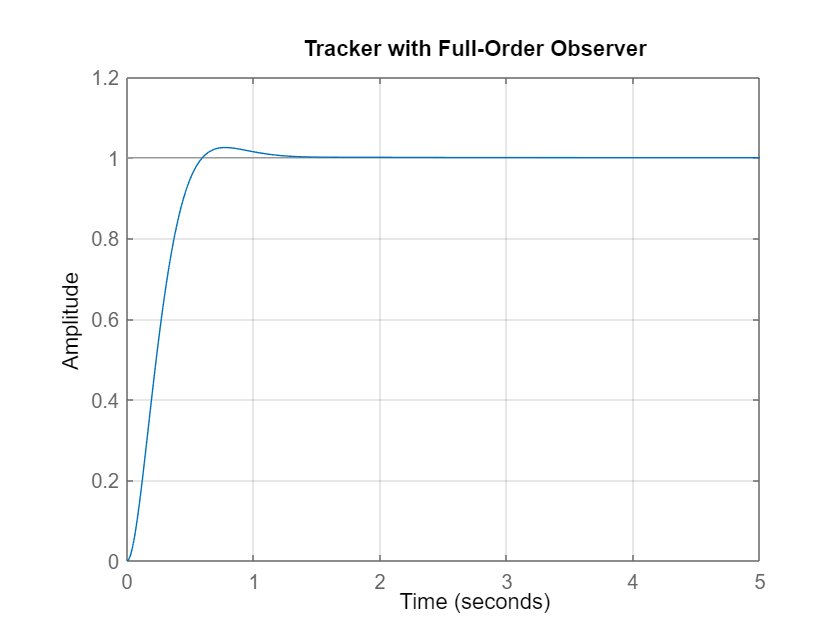

p_desired_regulator = [-5-4i, -5+4i, -1.5];
K = place(A, B, p_desired_regulator);

p_desired_observer = 10*p_desired_regulator;
L = place(A', C', p_desired_observer)';


A_reg = [   A-B*K          B*K;
        zeros(size(A))    A-L*C ];

B_reg = [     B*n_bar;
        zeros(size(B)) ];

C_reg = [     C    zeros(size(C)) ];


tFinal = 5;
t = 0:0.01:tFinal;      % time vector t = [0 ~ tFinal]
u = ones(size(t));      % step input u(t) = 1; for t>0
x0 = [0; 0; 0];         % zero state initial condition

figure;
hold on;
lsim(ss(A_reg,B_reg,C_reg,0), u, t, [0 0 0 0 0 0]);
title('Tracker with Full-Order Observer');
grid on;

**17.    ** Design a state feedback tracker with a reduced-order observer for the assumed system.

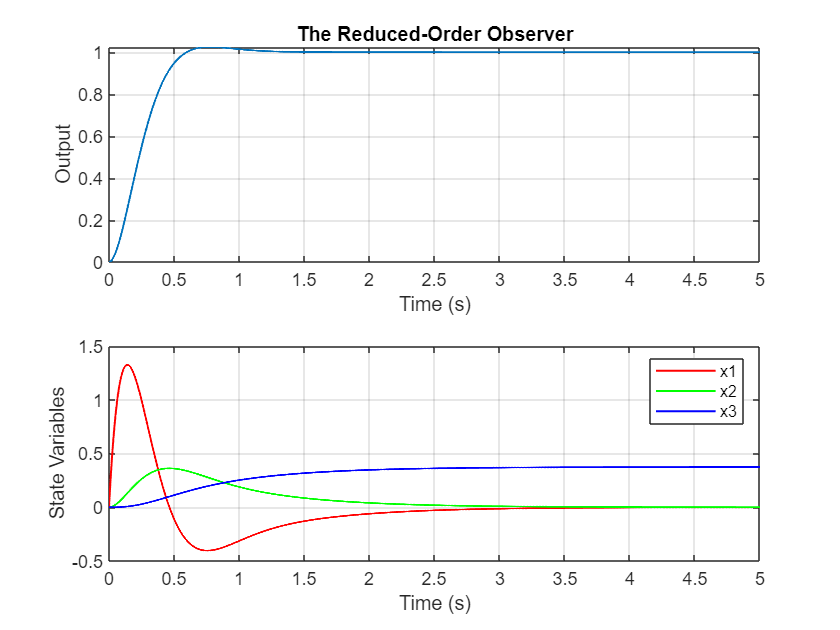

p_desired_regulator = [-5-4i, -5+4i, -1.5];
K = place(A, B, p_desired_regulator);

q = rank(C);
R = [   0   1   0   ;   
        1   0   0   ];
P = [   C   ; 
        R   ];

rank(P);
Q = inv(P);
Q1 = Q(1:3,1);
Q2 = Q(1:3,2:3);

A_bar = P*A*inv(P);
B_bar = P*B;
C_bar = C*inv(P);
D_bar = 0;

sys_singular = ss(A_bar, B_bar, C_bar, D_bar);

A11 = A_bar(1:q, 1:q);
A12 = A_bar(1:q, q+1:n);
A21 = A_bar(q+1:n, 1:q);
A22 = A_bar(q+1:n, q+1:n);

B1 = B_bar(1:q, :);
B2 = B_bar(q+1:n, :);

p_reduced_observer = 10*p_desired_regulator(1:n-q);
L_bar = place(A22', A12', p_reduced_observer)';

% Coefficients
cz = A22 - L_bar*A12;
cy = (A22 - L_bar*A12)*L_bar + (A21 - L_bar*A11);
cb = B2 - L_bar*B1;

A_est = [   A-B*K*Q1*C-B*K*Q2*L_bar*C          -B*K*Q2;
       cy*C-cb*K*Q1*C-cb*K*Q2*L_bar*C    cz-cb*K*Q2 ];
B_est = n_bar*[B; cb];
C_est = [C zeros(1,2)];

sys_est = ss(A_est,B_est,C_est,0);

tFinal = 5;
t = 0:0.001:tFinal;
u = ones(size(t));

[y, ~, z_est] = lsim(sys_est, u, t, [0 0 0 0 0]);
x_est = inv(P)*[y'; L_bar.*y'+z_est(:,4:end)'];

figure;
subplot(2, 1, 1);
plot(t, y, LineWidth=1);
title('The Reduced-Order Observer');
xlabel('Time (s)');
ylabel('Output');
grid on;

subplot(2, 1, 2);
plot(t, x_est(1,:), 'r', t, x_est(2,:), 'g', t, x_est(3,:), 'b', LineWidth=1);
legend('x1', 'x2', 'x3');
xlabel('Time (s)');
ylabel('State Variables');
grid on;

**18.    ** Obtain the optimal state feedback gain for the system to minimize the cost function for different R and Q matrix

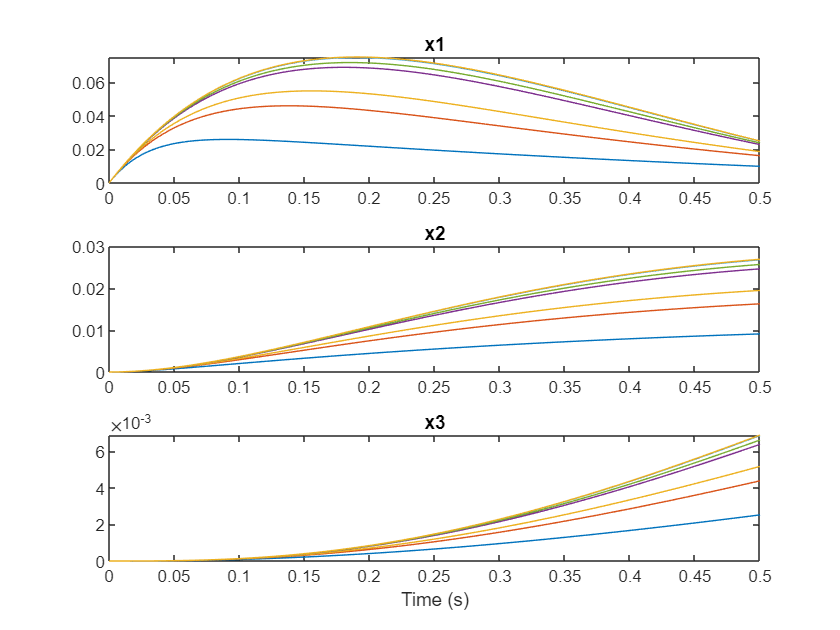

% Define the Q and R matrices
Q = eye(3); % a 3x3 identity matrix
R = 1; % a scalar value

% Obtain the optimal state feedback gain K
[K, S, e] = lqr(sys_controllable, Q, R);


% Plot the output response
figure;

% Simulate the system with different values of R
% different values of R to be tested
R_values = [ 0.001 0.005 0.01 0.05 0.1 1 5 10 50 100]; 
for i = 1:length(R_values)
    R = R_values(i);
    [K, S, e] = lqr(sys_controllable, Q, R);
    sys_lqr = ss(A-B*K, B, C, 0);
    
    t = 0:0.001:0.5;
    x0 = [0; 0; 0]; % initial state vector
    [y, t, x] = lsim(sys_lqr, ones(size(t)), t, x0);
    
    subplot(3,1,1);
    plot(t, x(:, 1));
    title('x1')
    hold on;
    subplot(3,1,2);
    plot(t, x(:, 2));
    title('x2')
    hold on;
    subplot(3,1,3);
    plot(t, x(:, 3));
    title('x3')
    hold on;
    xlabel('Time (s)');
end

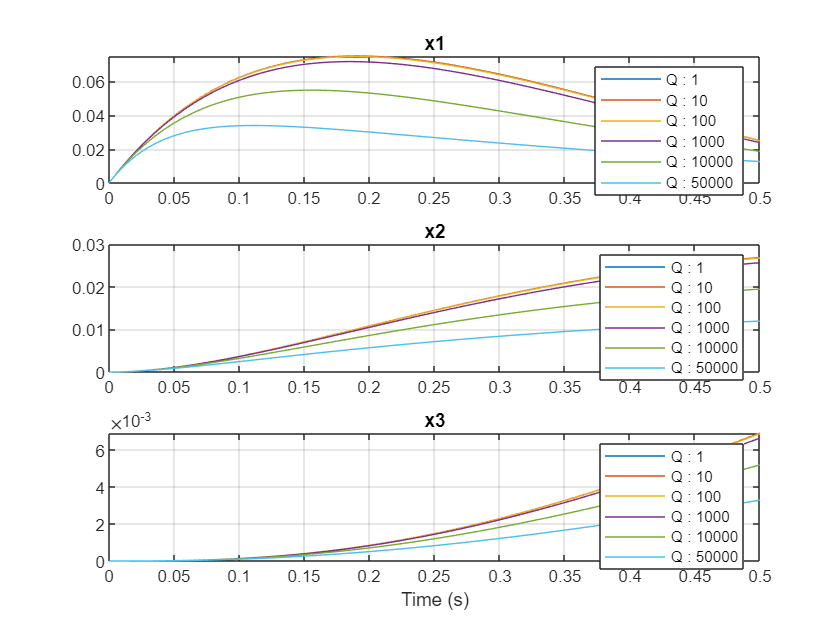

figure;

% Simulate the system with different values of Q
% different values of Q to be tested
Q_values = [ 1*eye(3); 10*eye(3); 100*eye(3); 1000*eye(3); 10000*eye(3); 50000*eye(3)];
for i = 1:length(Q_values)/3
    Q = Q_values(3*i-2:3*i,:);
    [K, S, e] = lqr(sys_controllable, Q, R);
    sys_lqr = ss(A-B*K, B, C, 0);

    Q_labels(i) = {["Q : " + num2str(Q_values(3*i-2,1))]};

    t = 0:0.001:0.5;
    x0 = [0; 0; 0]; % initial state vector
    [y, t, x] = lsim(sys_lqr, ones(size(t)), t, x0);
    
    % Plot the output response
    subplot(3,1,1);
    plot(t, x(:, 1));
    legend(Q_labels);
    title('x1')
    hold on;
    grid on;
    subplot(3,1,2);
    plot(t, x(:, 2));
    legend(Q_labels);
    title('x2')
    hold on;
    grid on;
    subplot(3,1,3);
    plot(t, x(:, 3));
    legend(Q_labels);
    title('x3')
    hold on;
    grid on;
    xlabel('Time (s)');
end